# Longitudinal Autopilot (Pitch + Altitude Hold)

% init
 clear; clc; close all;
addpath("Matlab\");
addpath("Simulink\");
[params, Vehicle, K] = initialize();

## Mission Requirements

disp("Pitch Requirements:");

Pitch Requirements:


fprintf("  Settling time <= %.2f s\n", params.requirements.settleSMax);

  Settling time <= 2.00 s


fprintf("  Overshoot     <= %.2f %%\n", params.requirements.overshootMax);

  Overshoot     <= 10.00 %


fprintf("  Steady error  <= %.2f deg\n", params.requirements.errDegMax);

  Steady error  <= 0.50 deg


## Vehicle Model Overview

Vehicle

Vehicle = struct with fields:
              name: 'Generic Longitudinal Vehicle (5-State)'
    trim_speed_mps: 30
                 A: [5×5 double]
                 B: [5×1 double]
                 C: [3×5 double]
                 D: [3×1 double]
            states: {'u'  'w'  'q'  'theta'  'h'}
           outputs: {'theta'  'q'  'h'}
            inputs: {'de'}
               sys: [3×1 ss]


## Open-Loop Dynamics Check

sys = Vehicle.sys;

disp("Open-loop eigenvalues:");

Open-loop eigenvalues:


openLoopEigenVals = eig(sys)

openLoopEigenVals =    0.0000 + 0.0000i
  -0.8255 + 6.1767i
  -0.8255 - 6.1767i
  -0.0195 + 0.1593i
  -0.0195 - 0.1593i


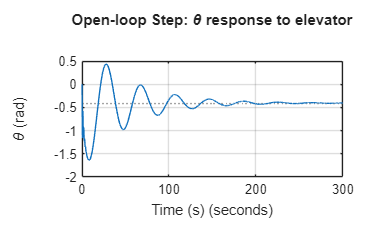


% Damping info
dampingInfo = damp(sys);

% Open-loop response from elevator to theta
figure;
step(sys(1,1));
grid on;
title('Open-loop Step: \theta response to elevator');
xlabel('Time (s)');
ylabel('\theta (rad)');

## Controller Summary/Tuning

K

K = struct with fields:
                  q: [1×1 struct]
              theta: [1×1 struct]
                  h: [1×1 struct]
    thetaCommandMax: 0.2618
              notes: 'Cascaded pitch autopilot: theta PI -> q_cmd, q P -> de_cmd'



% --- Manual tuning overrides (edit these) ---
K.q.Kp  = -0.60;     % inner loop gain
K.theta.Kp = 4.1;     % outer loop proportional
K.theta.Ki = 1.8;    % outer loop integral

% --- Noise Check ---
 params.sensors.qStd = 0;
 params.sensors.thetaStd = 0;

% Push updated gains to base workspace so Simulink uses them
assignin('base','K',K);
assignin('base', 'P', params);

## Run Simulink Simulation (Pitch Step Test)

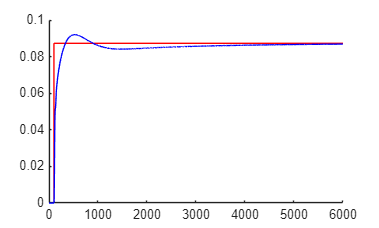

model = 'Autopilot';
load_system(model)

% Run pitch test
set_param(model, 'StopTime', num2str(P.endPitchTime));
simOut = sim(model);

% Extract Sim Results:
logs = simOut.logsout;
t = simOut.tout;

theta     = logs.get('theta').Values.Data;
theta_cmd = logs.get('theta_cmd').Values.Data;
theta_measured = logs.get('theta_measured').Values.Data;
q = []; h = []; de = []; de_cmd = []; 

if any(strcmp(logs.getElementNames,'q')),      q      = logs.get('q').Values.Data; end
if any(strcmp(logs.getElementNames,'h')),      h      = logs.get('h').Values.Data; end
if any(strcmp(logs.getElementNames,'de')),     de     = logs.get('de').Values.Data; end
if any(strcmp(logs.getElementNames,'de_cmd')), de_cmd = logs.get('de_cmd').Values.Data; end

figure
hold on
plot(theta_cmd, 'r')
plot(theta, 'b')


fprintf("theta_cmd(end)=%.4f, theta(end)=%.4f\n", theta_cmd(end), theta(end));

theta_cmd(end)=0.0873, theta(end)=0.0868


theta_measured(end)

ans = 0.0868

## Plot Pitch Tracking

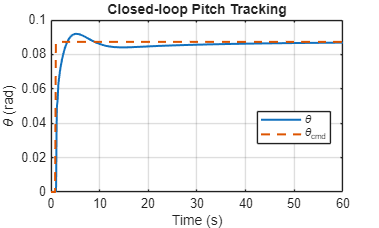

figure;
plot(t, theta, 'LineWidth', 1.5); hold on;
plot(t, theta_cmd, '--', 'LineWidth', 1.5);
grid on;
xlabel('Time (s)');
ylabel('\theta (rad)');
legend('\theta','\theta_{cmd}','Location','Best');
title('Closed-loop Pitch Tracking');

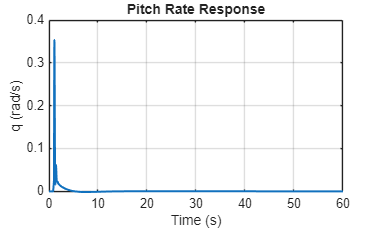


if ~isempty(q)
    figure;
    plot(t, q, 'LineWidth', 1.5); grid on;
    xlabel('Time (s)'); ylabel('q (rad/s)');
    title('Pitch Rate Response');
end

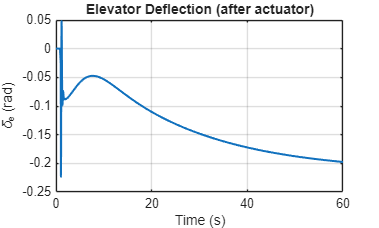


if ~isempty(de)
    figure;
    plot(t, de, 'LineWidth', 1.5); grid on;
    xlabel('Time (s)'); ylabel('\delta_e (rad)');
    title('Elevator Deflection (after actuator)');
end

## Compute Metrics

M_pitch = metricStep(t, theta, theta_cmd, 'Pitch Step');
disp(M_pitch);

                  name: "Pitch Step"
                   rms: 0.0054
          overshootPCT: 5.3631
         settlingTimeS: 1.3900
    steadyStateErrMean: -4.8816e-04
     steadyStateErrMax: 5.5667e-04




% Pass-Fail Table
deg = 180/pi;

Req = [
    "Settling time (<= " + params.requirements.settleSMax + " s)"
    "Overshoot (<= " + params.requirements.overshootMax + " %)"
    "Steady-state |error| (<= " + params.requirements.errDegMax + " deg)"
    ];

Value = [
    string(M_pitch.settlingTimeS)
    string(M_pitch.overshootPCT)
    string(M_pitch.steadyStateErrMax * deg)
    ];

Pass = [
    M_pitch.settlingTimeS <= params.requirements.settleSMax
    M_pitch.overshootPCT   <= params.requirements.overshootMax
    (M_pitch.steadyStateErrMax * deg) <= params.requirements.errDegMax
    ];

T_pitch = table(Req, Value, Pass);
T_pitch

T_pitch = 3×3 table
                    Req                      Value       Pass 
    ___________________________________    __________    _____

    "Settling time (<= 2 s)"               "1.39"        true 
    "Overshoot (<= 10 %)"                  "5.3631"      true 
    "Steady-state |error| (<= 0.5 deg)"    "0.031895"    true 
